org = Org; org.init;

figure;
org.correlogram('fixed_pss', 'inv_asymp_ratio', true, true, true);

Using only 72 out of 110 sessions
Mouse-aggregated correlations fixed_pss vs. inv_asymp_ratio: adj. R^2 = 0.378
Pearson: 0.669, p = 3.450464e-02, *
Spearman: 0.721, p = 2.419459e-02, *
Kendall: 0.556, p = 2.860946e-02, *


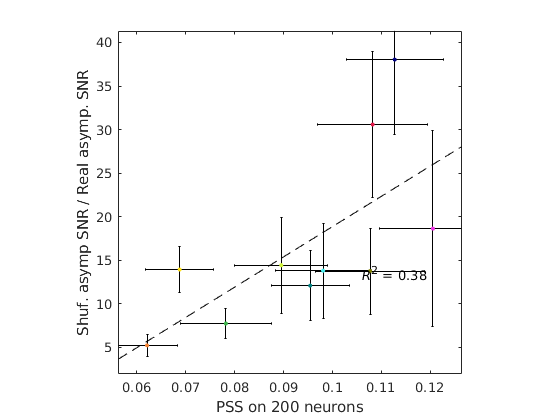

xlabel 'PSS on 200 neurons'
ylabel 'Shuf. asymp SNR / Real asymp. SNR'
axis square
Utils.printto('events_figs/f4_supplements', 'fixed_pss_by_mouse.pdf');

figure;
org.correlogram('fixed_pss', 'inv_asymp_ratio', false, true, true);

Using only 72 out of 110 sessions
Sessionwise correlations fixed_pss vs. inv_asymp_ratio: adj. R^2 = 0.253
Pearson: 0.514, p = 3.948804e-06, ***
Spearman: 0.469, p = 3.952239e-05, ***
Kendall: 0.329, p = 4.531038e-05, ***


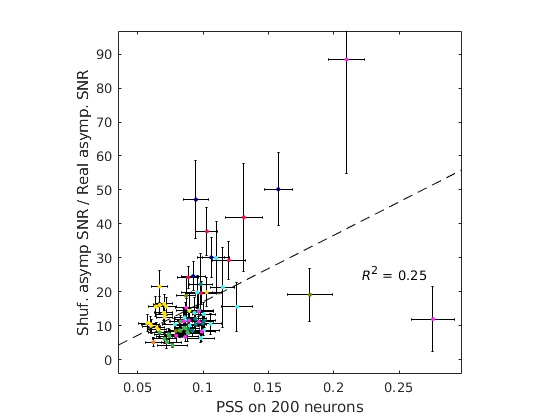

xlabel 'PSS on 200 neurons'
ylabel 'Shuf. asymp SNR / Real asymp. SNR'
axis square
Utils.printto('events_figs/f4_supplements', 'fixed_pss_by_sess.pdf');

figure;
org.correlogram('fixed_pss', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations fixed_pss vs. asymp_ratio: adj. R^2 = 0.393
Pearson: -0.679, p = 3.088519e-02, *
Spearman: -0.406, p = 2.473708e-01, n.s
Kendall: -0.333, p = 2.163735e-01, n.s


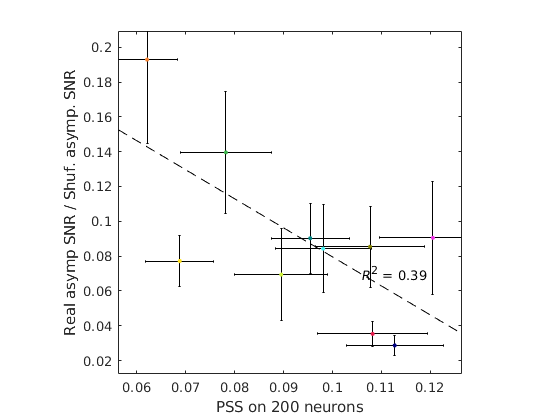

xlabel 'PSS on 200 neurons'
ylabel 'Real asymp SNR / Shuf. asymp. SNR'
axis square

%Utils.printto('events_figs/f4_supplements', 'fixed_pss_by_mouse.pdf');

dmus = org.fetch('dmus');

Checking the results using only sessions with > 300 neurons

sz = 300;
n_reps = 100;
pss_fixed = cellfun(@(ms)fixed_pss_over_bins(ms, sz, n_reps), dmus);

%hq_filt = SessManager.highqual_filt_from_usable;
hq_filt = org.sess_prop.num_neurons >= 300;

pss_fixed_highqual = pss_fixed(hq_filt);

inv_asymp_ratio_highqual = org.sess_prop.inv_asymp_ratio(hq_filt).';

n_neu = org.sess_prop.num_neurons(hq_filt).';

fitlm(pss_fixed_highqual, inv_asymp_ratio_highqual)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -18.548     5.0727    -3.6565     0.0013146
    x1              478.94      54.98     8.7111    9.6539e-09


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 8.68
R-squared: 0.767,  Adjusted R-Squared: 0.757
F-statistic vs. constant model: 75.9, p-value = 9.65e-09

fitlm(by_mouse_hq(pss_fixed_highqual, hq_filt), by_mouse_hq(inv_asymp_ratio_highqual, hq_filt))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat     pValue 
                   ________    ______    _______    _______

    (Intercept)    -22.406     20.237    -1.1072    0.34901
    x1               498.1     211.85     2.3512     0.1002


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 8.33
R-squared: 0.648,  Adjusted R-Squared: 0.531
F-statistic vs. constant model: 5.53, p-value = 0.1

fitlm(n_neu, inv_asymp_ratio_highqual)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue 
                   ________    ________    _______    _______

    (Intercept)    -41.181       25.822    -1.5948    0.12441
    x1             0.16305     0.065128     2.5035    0.01984


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 16
R-squared: 0.214,  Adjusted R-Squared: 0.18
F-statistic vs. constant model: 6.27, p-value = 0.0198

fitlm(n_neu, pss_fixed_highqual)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat     pValue 
                   __________    __________    _______    _______

    (Intercept)      0.014694      0.051086    0.28763    0.77621
    x1             0.00018298    0.00012885     1.4202    0.16898


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 0.0316
R-squared: 0.0806,  Adjusted R-Squared: 0.0406
F-statistic vs. constant model: 2.02, p-value = 0.169

function [v, m_names] = by_mouse_hq(vals, my_filt)
[~, hq_mice] = SessManager.usable_sess_id_list;
hq_mice = hq_mice(my_filt);
m_names = unique(hq_mice);
for i = 1:numel(m_names)
    filt = strcmp(hq_mice,m_names{i});
    v(i) = mean(vals(filt));
end
end

function p = fixed_pss_over_bins(ms, sz, n_reps)
not_empty = ~cellfun(@isempty, ms);
ms = ms(not_empty);
p = mean(cellfun(@(m)fixed_size_pss(m,sz,n_reps), ms));
end

function p = fixed_size_pss(m, sz, n_reps)
pss = zeros(n_reps,1);
n = numel(m);
for i = 1:n_reps
    select = randperm(n) <= sz;
    m_sub = m(select);
    pss(i) = compute_pss(m_sub);
end
p = mean(pss);
end

function p = compute_pss(dmu)
%m = m ./ vecnorm(m);
%p = 1./sum(m.^4);
%p = p ./ numel(m);
p = (sum(dmu.^2).^2 ./ sum(dmu.^4)) ./ length(dmu);
end